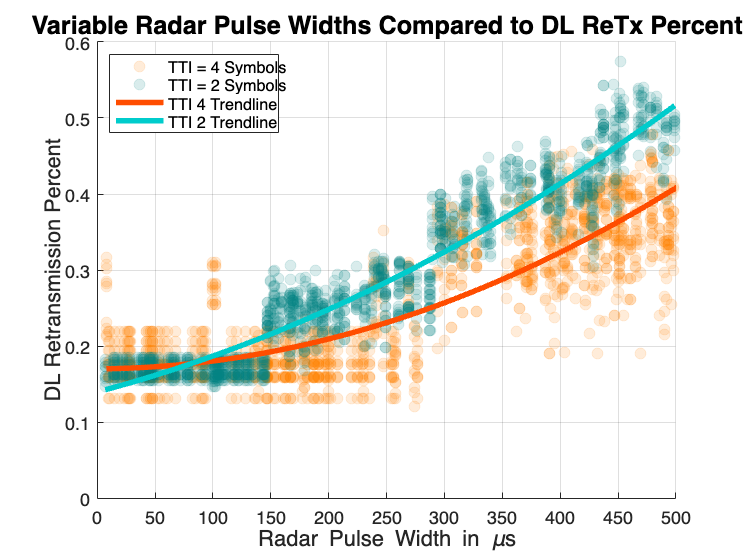

% Read data
data = readtable("Results/rndPW_PWIdx/rnd_PW_rnd_PWSltIdx_tti_4_1500.csv");
data_tti2 = readtable("Results/rndPW_PWIdx/rnd_PW_rnd_PWSltIdx_tti_2_1500.csv");
data.ReTxPrcnt = data.numReTx_DL ./ data.numDLTotal;
data_tti2.ReTxPrcnt = data_tti2.numReTx_DL ./ data_tti2.numDLTotal;

% Scatter plot for TTI = 4 (orange)
figure;
tti4 = scatter(data.PulseWidth, data.ReTxPrcnt, ...
    'MarkerFaceColor', [1, 0.5, 0], 'MarkerEdgeColor', [1, 0.5, 0], ... % Orange
    'MarkerFaceAlpha', 0.15, 'MarkerEdgeAlpha', 0.15); % Reduce scatter point opacity
hold on;

% Scatter plot for TTI = 2 (teal)
tti2 = scatter(data_tti2.PulseWidth, data_tti2.ReTxPrcnt, ...
    'MarkerFaceColor', [0, 0.5, 0.5], 'MarkerEdgeColor', [0, 0.5, 0.5], ... % Teal
    'MarkerFaceAlpha', 0.15, 'MarkerEdgeAlpha', 0.15); % Reduce scatter point opacity

% Set display names for legend
tti2.DisplayName = 'TTI = 2 Symbols';
tti4.DisplayName = 'TTI = 4 Symbols';

% Add second-degree trendline for TTI = 4 (bright orange, thicker line)
p4 = polyfit(data.PulseWidth, data.ReTxPrcnt, 2); % Fit a quadratic polynomial
x_fit4 = linspace(min(data.PulseWidth), max(data.PulseWidth), 100); % Generate smooth x values
y_fit4 = polyval(p4, x_fit4); % Evaluate the polynomial
plot(x_fit4, y_fit4, '-', 'Color', [1, 0.3, 0], 'LineWidth', 3, 'DisplayName', 'TTI 4 Trendline'); % Brighter orange, thicker line

% Add second-degree trendline for TTI = 2 (bright teal, thicker line)
p2 = polyfit(data_tti2.PulseWidth, data_tti2.ReTxPrcnt, 2); % Fit a quadratic polynomial
x_fit2 = linspace(min(data_tti2.PulseWidth), max(data_tti2.PulseWidth), 100); % Generate smooth x values
y_fit2 = polyval(p2, x_fit2); % Evaluate the polynomial
plot(x_fit2, y_fit2, '-', 'Color', [0, 0.8, 0.8], 'LineWidth', 3, 'DisplayName', 'TTI 2 Trendline'); % Brighter teal, thicker line

% Add title, labels, and axes limits
title('Variable Radar Pulse Widths Compared to DL ReTx Percent', 'FontSize', 14);
xlabel("Radar Pulse Width in \mus", 'FontSize', 12);
ylabel('DL Retransmission Percent', 'FontSize', 12);
xlim([0 500]);
ylim([0 0.6]);
grid on;

% Add legend
legend('Location', 'northwest');

hold off;


% Analyze Variance and Mean for TTI 2
tti2_t = 143; % Threshold for TTI = 2
tti4_t = 286; % Threshold for TTI = 4

% TTI 2: PW < TTI duration
disp('TTI 2: PW < TTI duration');

TTI 2: PW < TTI duration


var_tti2_low = var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= 0 & data_tti2.PulseWidth < tti2_t));
mean_tti2_low = mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= 0 & data_tti2.PulseWidth < tti2_t));
disp(['Variance: ', num2str(var_tti2_low), ', Mean: ', num2str(mean_tti2_low)]);

Variance: 0.00010392, Mean: 0.16905



% TTI 2: PW between TTI2 and TTI4 duration
disp('TTI 2: TTI2 <= PW < TTI4');

TTI 2: TTI2 <= PW < TTI4


var_tti2_mid = var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti2_t & data_tti2.PulseWidth < tti4_t));
mean_tti2_mid = mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti2_t & data_tti2.PulseWidth < tti4_t));
disp(['Variance: ', num2str(var_tti2_mid), ', Mean: ', num2str(mean_tti2_mid)]);

Variance: 0.0012032, Mean: 0.24953



% TTI 2: PW > TTI4 duration
disp('TTI 2: PW >= TTI4 duration');

TTI 2: PW >= TTI4 duration


var_tti2_high = var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti4_t & data_tti2.PulseWidth < 500));
mean_tti2_high = mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti4_t & data_tti2.PulseWidth < 500));
disp(['Variance: ', num2str(var_tti2_high), ', Mean: ', num2str(mean_tti2_high)]);

Variance: 0.0040831, Mean: 0.40939



% Analyze Variance and Mean for TTI 4
disp('TTI 4: Analysis');

TTI 4: Analysis


var_tti4_low = var(data.ReTxPrcnt(data.PulseWidth >= 0 & data.PulseWidth < tti4_t));
mean_tti4_low = mean(data.ReTxPrcnt(data.PulseWidth >= 0 & data.PulseWidth < tti4_t));
disp(['Variance (PW < TTI4): ', num2str(var_tti4_low), ', Mean: ', num2str(mean_tti4_low)]);

Variance (PW < TTI4): 0.0014033, Mean: 0.18455



var_tti4_high = var(data.ReTxPrcnt(data.PulseWidth >= tti4_t & data.PulseWidth < 500));
mean_tti4_high = mean(data.ReTxPrcnt(data.PulseWidth >= tti4_t & data.PulseWidth < 500));
disp(['Variance (PW >= TTI4): ', num2str(var_tti4_high), ', Mean: ', num2str(mean_tti4_high)]);

Variance (PW >= TTI4): 0.0026352, Mean: 0.34642
